**Project: Image Stitching - Mars Rover Panorama**

% Project Introduction:
% This project aims to create a seamless panoramic image from multiple photos
% taken by the Mars Rover. The input consists of two overlapping images captured
% by the rover's navigation camera. The goal is to align (register) the images
% accurately using feature matching and geometric transformation, then blend them
% to form a wide-angle panoramic view of the Martian surface.
%
% The steps include:
% 1. Loading the fixed and moving images.
% 2. Registering the moving image to the fixed image via feature matching.
% 3. Calculating output limits and creating a suitable panorama canvas.
% 4. Warping and blending images to create a smooth panorama.
% 5. Testing and visualizing the final stitched result.
%
% This project demonstrates fundamental image processing concepts such as 
% image registration, geometric transformation, warping, and blending,
% applied to real-world planetary exploration data.


**Section 1: Load Images**

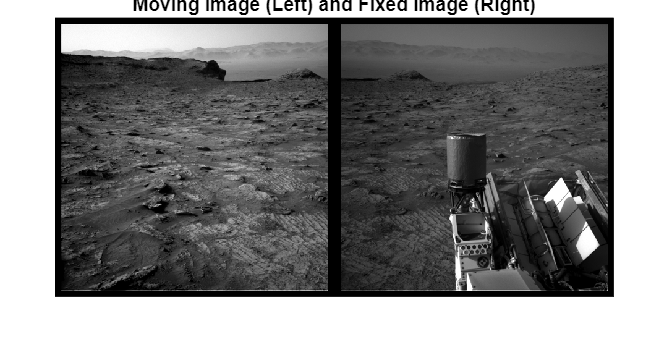

fixedImg = imread("sol_03333_opgs_edr_ncam_NLB_693387385EDR_F0921230NCAM00259M_.JPG");
movingImg = imread("sol_03333_opgs_edr_ncam_NLB_693387301EDR_F0921230NCAM00259M_.JPG");

figure; montage({movingImg, fixedImg}, 'BorderSize', [10 10]);
title('Moving Image (Left) and Fixed Image (Right)');

**Section 2: Register the Images**

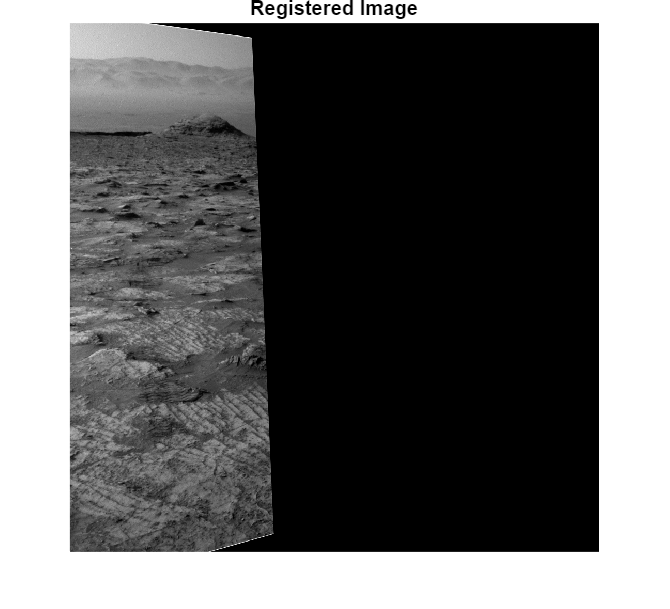

reg = registerMarsImages(movingImg, fixedImg);

figure; imshow(reg.RegisteredImage);
title('Registered Image');

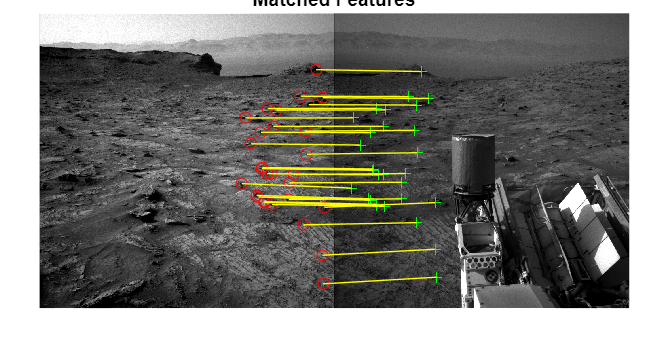


figure;
showMatchedFeatures(movingImg, fixedImg, reg.MovingMatchedFeatures, reg.FixedMatchedFeatures, 'montage');
title('Matched Features');

**Section 3: Initialize the Panorama**

movingT = reg.Transformation;
fixedT = rigidtform2d();

[nRows, nCols, ~] = size(movingImg);

[xlimMoving, ylimMoving] = outputLimits(movingT, [1 nCols], [1 nRows]);
[xlimFixed, ylimFixed] = outputLimits(fixedT, [1 nCols], [1 nRows]);

xMin = min([xlimFixed, xlimMoving]);
xMax = max([xlimFixed, xlimMoving]);
yMin = min([ylimFixed, ylimMoving]);
yMax = max([ylimFixed, ylimMoving]);

w = round(xMax - xMin);
h = round(yMax - yMin);

panorama = zeros([h, w], "uint8");
panoramaView = imref2d([h w], [xMin xMax], [yMin yMax]);


**Section 4: Create the Panorama**

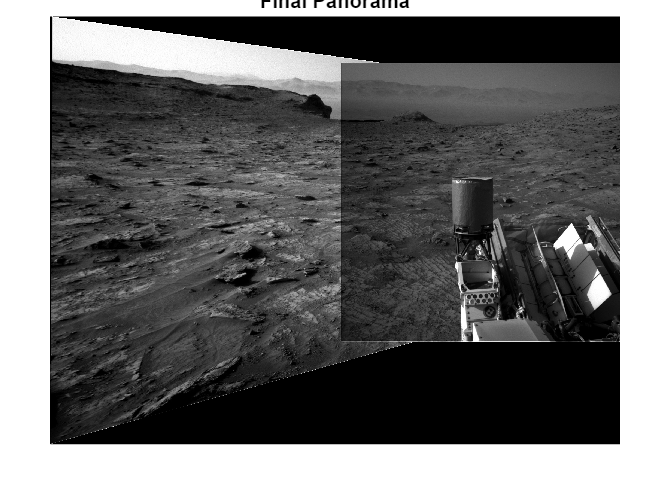

blender = vision.AlphaBlender('Operation', 'Binary mask', 'MaskSource', 'Input port');

movingWarped = imwarp(movingImg, movingT, 'OutputView', panoramaView);
fixedWarped = imwarp(fixedImg, fixedT, 'OutputView', panoramaView);

mask = true(nRows, nCols);
movingMask = imwarp(mask, movingT, 'OutputView', panoramaView);
fixedMask = imwarp(mask, fixedT, 'OutputView', panoramaView);

panorama = blender(panorama, movingWarped, movingMask);
panorama = blender(panorama, fixedWarped, fixedMask);

figure; imshow(panorama);
title('Final Panorama');

% Save the final image
imwrite(panorama, 'mars_panorama.jpg');
disp('Panorama saved as mars_panorama.jpg');

Panorama saved as mars_panorama.jpg


**Helper Function: registerMarsImages()**

function [MOVINGREG] = registerMarsImages(MOVING,FIXED)
%registerMarsImages  Register grayscale images using auto-generated code from Registration Estimator app.
%  [MOVINGREG] = registerMarsImages(MOVING,FIXED) registers grayscale images
%  MOVING and FIXED using parameters set interactively in the app. The
%  function returns the registered image and transformation details in the
%  structure array MOVINGREG.
%
%  Auto-generated by registrationEstimator app on 15-May-2025
%-----------------------------------------------------------

% Convert to grayscale if the inputs are RGB
if size(MOVING,3) == 3
    MOVING = rgb2gray(MOVING);
end
if size(FIXED,3) == 3
    FIXED = rgb2gray(FIXED);
end

% Feature-based techniques require a license for the Computer Vision Toolbox
checkLicense();

% Default spatial referencing objects
fixedRefObj = imref2d(size(FIXED));
movingRefObj = imref2d(size(MOVING));

% Detect SURF features
fixedPoints = detectSURFFeatures(FIXED,'MetricThreshold',857.499886,'NumOctaves',2,'NumScaleLevels',4);
movingPoints = detectSURFFeatures(MOVING,'MetricThreshold',857.499886,'NumOctaves',2,'NumScaleLevels',4);

% Extract features from the images
[fixedFeatures,fixedValidPoints] = extractFeatures(FIXED,fixedPoints,'Upright',false);
[movingFeatures,movingValidPoints] = extractFeatures(MOVING,movingPoints,'Upright',false);

% Match features between the two images
indexPairs = matchFeatures(fixedFeatures,movingFeatures,'MatchThreshold',15.499954,'MaxRatio',0.155000);
fixedMatchedPoints = fixedValidPoints(indexPairs(:,1));
movingMatchedPoints = movingValidPoints(indexPairs(:,2));
MOVINGREG.FixedMatchedFeatures = fixedMatchedPoints;
MOVINGREG.MovingMatchedFeatures = movingMatchedPoints;

% Apply transformation - Results may not be identical between runs because of
% the randomized nature of the RANSAC algorithm.
tform = estimateGeometricTransform2D(movingMatchedPoints,fixedMatchedPoints,'projective');
MOVINGREG.Transformation = tform;
MOVINGREG.RegisteredImage = imwarp(MOVING, movingRefObj, tform, 'OutputView', fixedRefObj, 'SmoothEdges', true);

% Store spatial referencing object
MOVINGREG.SpatialRefObj = fixedRefObj;

end

function checkLicense()
% Check for license to Computer Vision Toolbox
CVTStatus = license('test','Video_and_Image_Blockset');
if ~CVTStatus
    error(message('images:imageRegistration:CVTRequired'));
end
end
